b = [1];
a = conv([1 -0.8],[1 -0.8]);
a = conv(a,[1 +0.8]);
[r,p,k] = residuez(b,a)

a = [1 -2*cos(2*pi/5) 1];
b = [0];
Y = [3*cos(pi/6-2*pi/5) 3*cos(pi/6 - 4*pi/5)];
xic = filtic(b, a, Y);
yzi = filter(b,a,zeros(1,20),xic)

yzi =     2.5981   -0.6237   -2.9836   -1.2202    2.2294    2.5981   -0.6237   -2.9836   -1.2202    2.2294    2.5981   -0.6237   -2.9836   -1.2202    2.2294    2.5981   -0.6237   -2.9836   -1.2202    2.2294


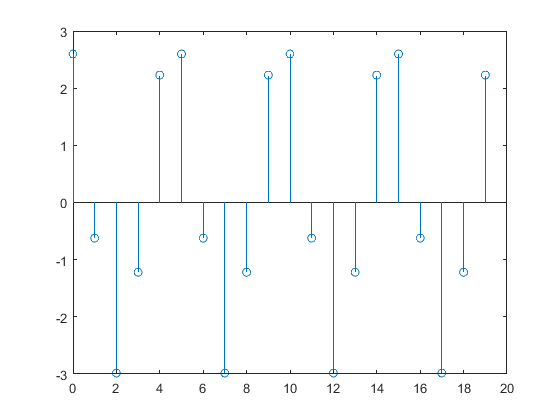

n = 0:19;
stem(n, yzi)

b = [1/3 1/3 1/3];
a=[1 -0.95 0.9025];
Y=[-2 -3];
X=[1 1];
xic = filtic(b,a,Y,X)

xic =     1.4742    2.1383


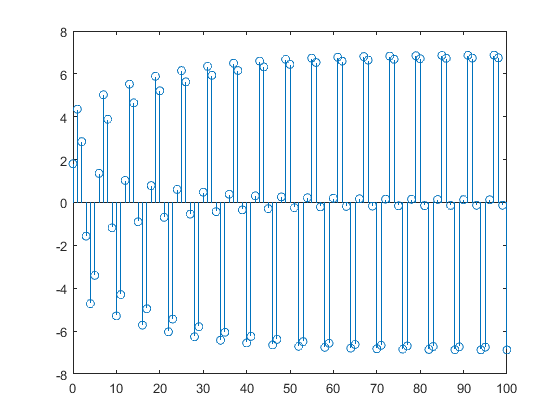


n = 0:1:100;
x = cos(pi*n/3);
y = filter(b,a,x,xic);
stem(n,y)

w = 0:(2*pi/10):8*pi;
n = 0:1:30

;
WN = n' * w;
size(WN)

ans =     31    41


y = exp(j .* WN);
stem(w, y(2,:));

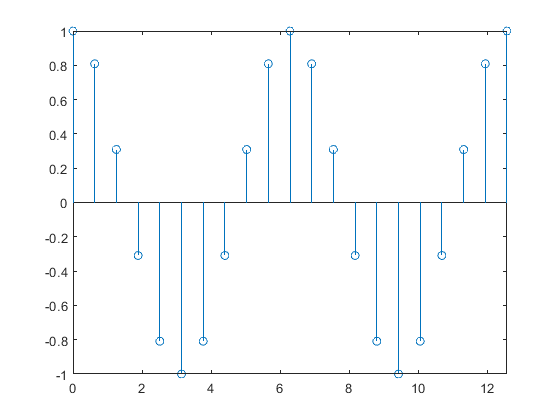

axis([0 4*pi -1 1]);

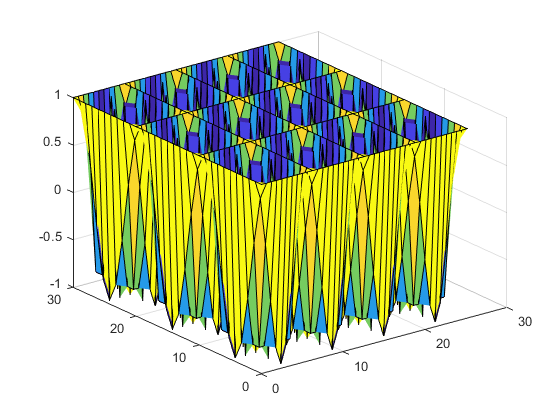

figure;
surf(w,n,real(y));

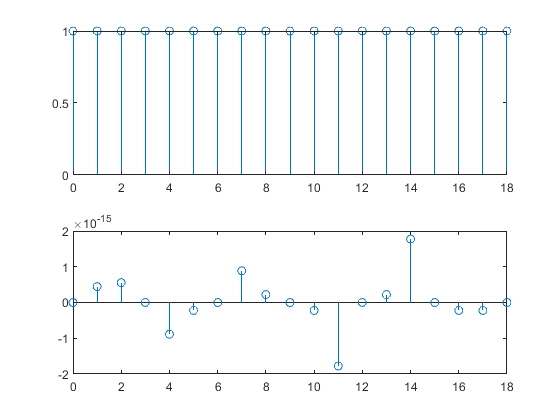

w = pi/3;
n = 0:1:18;
y = exp(i*w*n);
subplot(2,1,1);
stem(n,abs(y));
subplot(2,1,2);
stem(n,angle(y));

n2 = n + 6;
y2 = exp(i*w*n2);
stem(n, y2 - y)

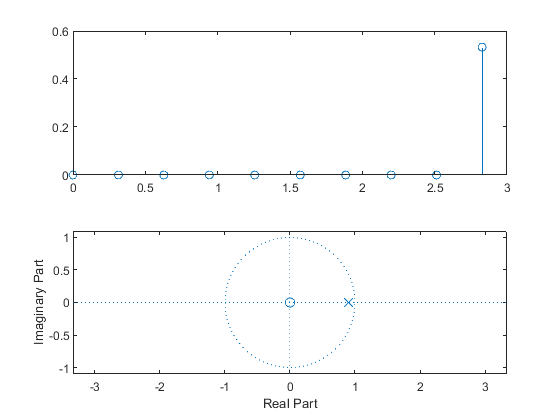

b = [1];
a = [1 -0.9];
zplane(b,a);

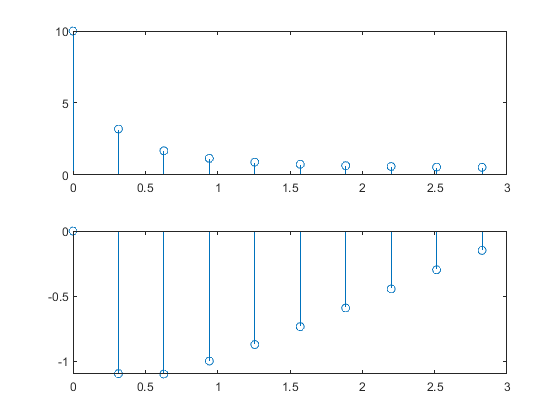

figure;
[h, w] = freqz(b,a,10);
subplot(2,1,1);
stem(w,abs(h));
subplot(2,1,2);
stem(w, angle(h));

figure;
hw = 1 ./ (1 - 0.9 ./ exp(i*w));
subplot(2,1,1);
stem(w,abs(hw));
subplot(2,1,2);
stem(w,angle(hw));

b=[0 1 1]; a = [1 -0.9 0.81];
[r,p,k] = residuez(b,a)

r =   -0.6173 - 0.9979i
  -0.6173 + 0.9979i


p =    0.4500 + 0.7794i
   0.4500 - 0.7794i


k = 1.2346

abs(r)

ans =     1.1734
    1.1734


angle(r)/pi

ans =    -0.6763
    0.6763


abs(p)

ans =     0.9000
    0.9000


angle(p)/pi

ans =     0.3333
   -0.3333
